% 1. Set basic model parameters
a = 1.1;
% params.K_BN = 250;      
% params.K_HN = 50;      
params.K_HM = 30;      
params.Y_B = 0.5;        
params.Y_HN = 0.5;     
params.Y_HM = 1;       
params.delta_N = 0;  
params.alpha = 5;
params.gamma = 0.1;
params.Ncrit = 20;     
params.h = 8;   
params.mu_B = 0.2; 
params.mu_H = 1;   
params.delta_A = 0.1;
params.K_BD = 1;
params.epsilon = 0.6;
params.kappa = 2;
params.Y_BD = 1;

N0 = 500; B0 = 1; M0 = 10; H0 = 5;
tspan = [0 150];
y0_co = [N0; B0; H0; M0; 0; 0];

% 2. Set sweep range (modified to K_BN and K_HN)
K_BN_range = 1:4:500;
K_HN_range = 1:4:500;

num_K_BN = length(K_BN_range);
num_K_HN = length(K_HN_range);

% 3. Initialize storage matrices
% B_matrix: 2D matrix (rows correspond to K_HN, columns correspond to K_BN)
B_matrix = zeros(num_K_HN, num_K_BN);

% result_final_matrix: 3D matrix (3rd dimension length = 5), storing:
% [B_co, H_co, B_mono, cum_self_final_co, cum_self_final_mono]
result_final_matrix = zeros(num_K_HN, num_K_BN, 5);

% 4. Double loop for parameter sweep
disp('Starting parameter sweep, please wait...');

Starting parameter sweep, please wait...


for i = 1:num_K_HN
    for j = 1:num_K_BN
        % Extract current K_BN and K_HN values
        current_K_HN = K_HN_range(i);
        current_K_BN = K_BN_range(j);
        
        % Update dynamic parameters
        params.K_BN = current_K_BN;
        params.K_HN = current_K_HN;
        
        result = model_output(params);
        
        % Save biomass difference (B_co - B_mono)
        B_matrix(i, j) = result(1) - result(3);
        
        % Save complete result vector
        result_final_matrix(i, j, :) = result;
    end
end
disp('Parameter sweep completed!');

Parameter sweep completed!


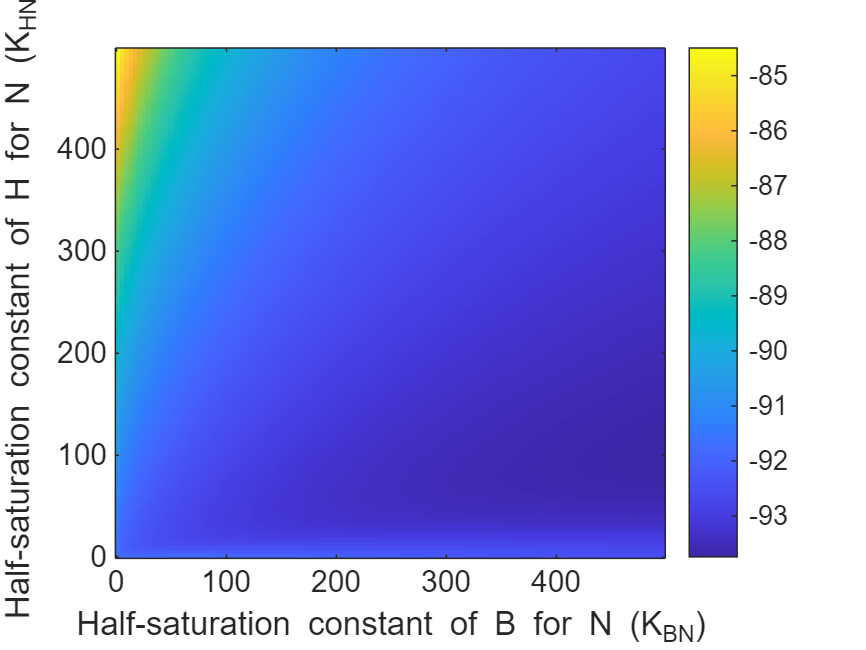


% 5. Plot heatmap of biomass difference with zero boundary contour
figure;
imagesc(K_BN_range, K_HN_range, B_matrix);
set(gca, 'YDir', 'normal'); % Set Y-axis direction ascending upwards
colormap(parula);           % Can be changed to 'jet' or 'turbo'
colorbar;

% Add contour line for B_co - B_mono = 0
hold on;
[C, h_contour] = contour(K_BN_range, K_HN_range, B_matrix, [0 0], 'LineColor', 'r', 'LineWidth', 2);
clabel(C, h_contour, 'FontSize', 12, 'Color', 'r', 'FontWeight', 'bold');
hold off;

xlabel('Half-saturation constant of B for N (K_{BN})');
ylabel('Half-saturation constant of H for N (K_{HN})');